ulog = ulogreader("08_56_49.ulg");
msg = readTopicMsgs(ulog);
d1 = ulog.StartTime;
d2 = ulog.EndTime;

data = readTopicMsgs(ulog,'TopicNames',{'actuator_feedback'}, ... 
'InstanceID',{0},'Time',[d1 d2]);
actuator_feedback = data.TopicMessages{1,1};

data = readTopicMsgs(ulog,'TopicNames',{'vehicle_thrust_setpoint'}, ... 
'InstanceID',{0},'Time',[d1 d2]);
vehicle_thrust_setpoint = data.TopicMessages{1,1};

data = readTopicMsgs(ulog,'TopicNames',{'vehicle_torque_setpoint'}, ... 
'InstanceID',{0},'Time',[d1 d2]);
vehicle_torque_setpoint = data.TopicMessages{1,1};

data = readTopicMsgs(ulog,'TopicNames',{'qp_solver_status'}, ... 
'InstanceID',{0},'Time',[d1 d2]);
qp_solver_status = data.TopicMessages{1,1};


prob = osqp;
settings = prob.default_settings();
settings.verbose = false;
ub = [35*9.8;
      35*9.8;
      0;
      deg2rad(22);
      deg2rad(27);
      deg2rad(22)];
lb = [2.3*9.8;
      2.3*9.8;
      deg2rad(-27);
      deg2rad(-22);
      deg2rad(0);
      deg2rad(-22)];
prob.setup(diag(ones(1,6)), ones(1,6), diag(ones(1,6)), lb, ub,settings);
factor_ = 1;
scale_factor_ = [factor_ factor_ 1 1 1 1];
config.l_x = 0.045;
config.l_y = 0.555;
config.l_z = 0.225;
config.l_d = 0.210;
config.theta_tilt = 8/180*pi;
torque_force_tar_pre = zeros(height(actuator_feedback),6);
du = zeros(height(actuator_feedback),6);
u = zeros(height(actuator_feedback),6);
du_cmd = zeros(height(actuator_feedback),4);
inv_delta = zeros(height(actuator_feedback),1);
obj_val = zeros(height(actuator_feedback),1);

b = [actuator_feedback.torque_roll_cmd,actuator_feedback.torque_pitch_cmd,actuator_feedback.torque_yaw_cmd,...
    actuator_feedback.thrust_x_cmd,actuator_feedback.thrust_y_cmd,actuator_feedback.thrust_z_cmd];
for i = 1:height(actuator_feedback)
    config.theta_r = actuator_feedback.theta_right(i);
    config.theta_l = actuator_feedback.theta_left(i);
    config.F_1 = actuator_feedback.f1(i);
    config.F_2 = actuator_feedback.f2(i);
    config.F_3 = actuator_feedback.f3(i);
    config.F_4 = actuator_feedback.f4(i);
    config.F_5 = actuator_feedback.f5(i);
    config.F_6 = actuator_feedback.f6(i);
    actuator_pre = [actuator_feedback.f1(i);
        actuator_feedback.f2(i);
        actuator_feedback.f3(i);
        actuator_feedback.f4(i);
        actuator_feedback.f5(i);
        actuator_feedback.f6(i);
        actuator_feedback.theta_right(i);
        actuator_feedback.theta_left(i)];
    torque_force_tar_pre(i,:) = getPreFT(config);
    Jacobe = getFTjacobe(config); 
    Jacobe_stm = reshape(actuator_feedback.effectiveness(i,:)',4,6);

    Jacobe_inv = reshape(actuator_feedback.effectiveness_inv(i,:)',6,4);
    inv_delta(i) = norm(Jacobe_inv - pinv(Jacobe_stm));
%     inv_delta(i) = norm(Jacobe_inv - geninv_single(single(Jacobe_stm)));
    
%     du(i,:) = geninv_single(single(Jacobe))*(b(i,[1:3,6]))';
%     du(i,:) = pinv(Jacobe)*(b(i,[1:3,6]))';
%     du(i,:) = lsqminnorm(Jacobe,(b(i,[1:3,6]))');

%     du(i,:) = du(i,:).*scale_factor_;
        H  = reshape(actuator_feedback.effectiveness(i,:)',4,6);
        f = b(i,[1:3,6])';
        P = sparse(H'*H);
        q = -(f'*H)';
      prob.update('Px',nonzeros(triu(P)), ...
          'q',q, ...
          'l',lb - actuator_pre(1:6), ...
          'u',ub - actuator_pre(1:6));
      res = prob.solve();
        obj_val(i) = res.info.obj_val;

      du(i,:) = res.x.*scale_factor_';

    u(i,:) = du(i,:) + [config.F_1,config.F_2,config.F_3,config.F_4,config.F_5,config.F_6];
    actuator_cmd_d = [actuator_feedback.f1_d(i),actuator_feedback.f2_d(i),...
                    actuator_feedback.f3_d(i),actuator_feedback.f4_d(i),...
                    actuator_feedback.f5_d(i),actuator_feedback.f6_d(i)];
    du_cmd(i,:) = (Jacobe*actuator_cmd_d')';
end

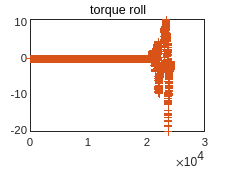

figure;
plot(torque_force_tar_pre(:,1));
hold on;
plot(actuator_feedback.torque_roll,'+');
hold off;
title('torque roll');

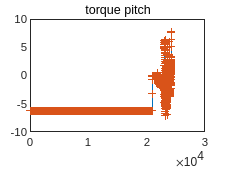

figure;
plot(torque_force_tar_pre(:,2));
hold on;
plot(actuator_feedback.torque_pitch,'+');
hold off;
title('torque pitch');

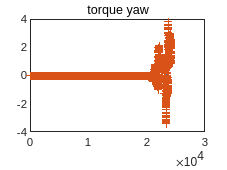

figure;
plot(torque_force_tar_pre(:,3));
hold on;
plot(actuator_feedback.torque_yaw,'+');
hold off;
title('torque yaw');

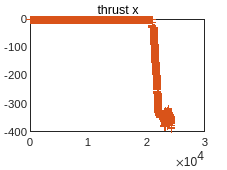

figure;
plot(torque_force_tar_pre(:,4));
hold on;
plot(actuator_feedback.thrust_x,'+');
hold off;
title('thrust x');

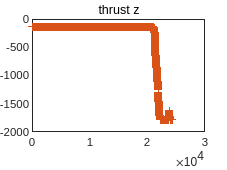

figure;
plot(torque_force_tar_pre(:,6));
hold on;
plot(actuator_feedback.thrust_z,'+');
hold off;
title('thrust z');


% figure;
% plot(vehicle_torque_setpoint.xyz(:,2));
% hold on;
% plot(torque_force_tar_pre(:,2),'+');
% hold off;
% title('thrust z');


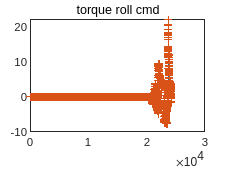


figure;
plot(du_cmd(:,1));
hold on;
plot(actuator_feedback.torque_roll_cmd,'+');
hold off;
title('torque roll cmd');

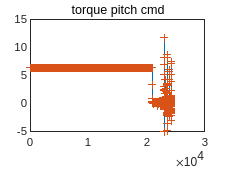

figure;
plot(du_cmd(:,2));
hold on;
plot(actuator_feedback.torque_pitch_cmd,'+');
hold off;
title('torque pitch cmd');

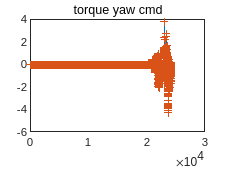

figure;
plot(du_cmd(:,3));
hold on;
plot(actuator_feedback.torque_yaw_cmd,'+');
hold off;
title('torque yaw cmd');

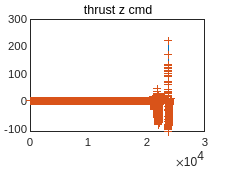

figure;
plot(du_cmd(:,4));
hold on;
plot(actuator_feedback.thrust_z_cmd,'+');
hold off;
title('thrust z cmd');

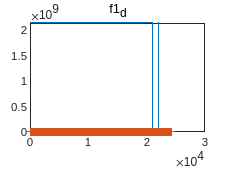

% figure;
% plot(du_cmd(:,5));
% hold on;
% plot(actuator_feedback.thrust_y_cmd,'+');
% hold off;
% title('thrust y cmd');
% figure;
% plot(du_cmd(:,6));
% hold on;
% plot(actuator_feedback.thrust_z_cmd,'+');
% hold off;
% title('thrust z cmd');

figure;
plot(du(:,1));
hold on;
plot(actuator_feedback.f1_d,'+');
hold off;
title('f1_d');

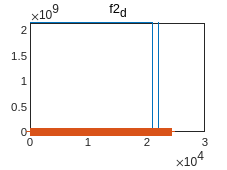

figure;
plot(du(:,2));
hold on;
plot(actuator_feedback.f2_d,'+');
hold off;
title('f2_d');

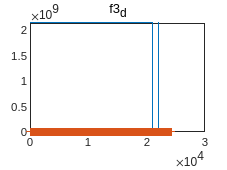

figure;
plot(du(:,3));
hold on;
plot(actuator_feedback.f3_d,'+');
hold off;
title('f3_d');

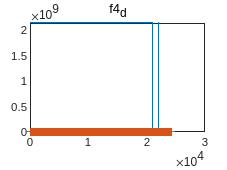

figure;
plot(du(:,4));
hold on;
plot(actuator_feedback.f4_d,'+');
hold off;
title('f4_d');

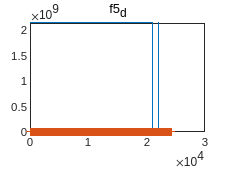

figure;
plot(du(:,5));
hold on;
plot(actuator_feedback.f5_d,'+');
hold off;
title('f5_d');

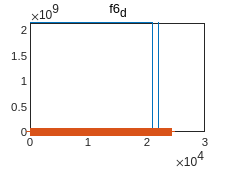

figure;
plot(du(:,6));
hold on;
plot(actuator_feedback.f6_d,'+');
hold off;
title('f6_d');

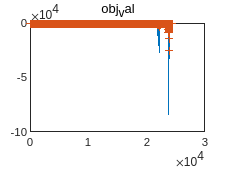


figure;
plot(obj_val);
hold on;
plot(qp_solver_status.problem1_obj_val,'+');
hold off;
title('obj_val');

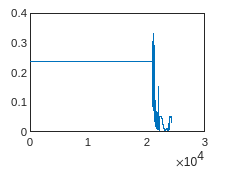


figure;
plot(inv_delta);

## test

% cut_res = geninv_single(TTest);
% res = geninv_single(Jacobe);
effe = actuator_feedback.effectiveness;

i = 3546;
A_ = reshape(effe(i,:)',4,6)

A_ =    -1.6650    1.6650   15.6555         0   15.6555         0
   -0.1350   -0.1350         0   15.6555         0   15.6555
         0         0   -3.1311   38.6169   -3.1311  -38.6169
   -3.0000   -3.0000         0         0         0         0


A_inv = reshape(actuator_feedback.effectiveness_inv(i,:)',6,4)

A_inv =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0



config.theta_r = actuator_feedback.theta_right(i);
config.theta_l = actuator_feedback.theta_left(i);
config.F_1 = actuator_feedback.f1(i);
config.F_2 = actuator_feedback.f2(i);
config.F_3 = actuator_feedback.f3(i);
config.F_4 = actuator_feedback.f4(i);
config.F_5 = actuator_feedback.f5(i);
config.F_6 = actuator_feedback.f6(i);
actuator_pre = [actuator_feedback.f1(i);
    actuator_feedback.f2(i);
    actuator_feedback.f3(i);
    actuator_feedback.f4(i);
    actuator_feedback.f5(i);
    actuator_feedback.f6(i);
    actuator_feedback.theta_right(i);
    actuator_feedback.theta_left(i)];
torque_force_tar_pre(i,:) = getPreFT(config);
Jacobe = getFTjacobe(config)

Jacobe = 4×6 single 矩阵
   -1.6650    1.6650   15.6555         0   15.6555         0
   -0.1350   -0.1350         0   15.6555         0   15.6555
         0         0   -3.1311   38.6169   -3.1311  -38.6169
   -3.0000   -3.0000         0         0         0         0


du(i,:) = geninv_single(single(Jacobe))*(b(i,[1:3,6]))';
jacobe_inv_ = lsqminnorm(A_,(b(i,[1:3,6]))');
% du(i,:) = du(i,:).*scale_factor_;
res = geninv_single(A_);
config

config = 包含以下字段的 struct :
           l_x: 0.0450
           l_y: 0.5550
           l_z: 0.2250
           l_d: 0.2100
    theta_tilt: 0.1396
       theta_r: 0
       theta_l: 0
           F_1: 23.1933
           F_2: 23.1933
           F_3: 0
           F_4: 0
           F_5: 0
           F_6: 0


(A_inv - geninv_single(A_))

ans = 6×4 single 矩阵
    0.0034   -0.0000    0.0001    0.1667
   -0.0034   -0.0000   -0.0001    0.1667
   -0.0316         0    0.0000         0
   -0.0026   -0.0319   -0.0129    0.0014
   -0.0316         0    0.0000         0
    0.0026   -0.0319    0.0129    0.0014


norm(A_inv - geninv_single(A_))

ans = single
0.2357

%         -1.7693503      1.7734275       -31.179199      95.351959       -31.527634      -88.081497
%         -0.0091013089   -0.018955372    -18.261652      220.9496         18.4939        223.22571
%         0.33142015      -0.30792895     -38.809574      525.93866       -39.312763      -533.00708
%         -2.677294       -2.6835685      -405.81448      144.28189       410.97556       133.28581

function jacobe = getFTjacobe(config)
l_x = config.l_x;
l_y = config.l_y;
l_z = config.l_z;
l_d = config.l_d;

F_r = config.F_1;
F_l = config.F_2;
theta_rr = config.F_3;
theta_rp = config.F_4;
theta_lr = config.F_5;
theta_lp = config.F_6;

% T_jacob = [- l_y*cos(theta_r)*cos(theta_tilt) - l_z*cos(theta_r)*sin(theta_tilt), - l_y*cos(theta_r)*cos(theta_tilt) - l_z*cos(theta_r)*sin(theta_tilt), - l_y*cos(theta_r)*cos(theta_tilt) - l_z*cos(theta_r)*sin(theta_tilt), l_y*cos(theta_l)*cos(theta_tilt) + l_z*cos(theta_l)*sin(theta_tilt), l_y*cos(theta_l)*cos(theta_tilt) + l_z*cos(theta_l)*sin(theta_tilt), l_y*cos(theta_l)*cos(theta_tilt) + l_z*cos(theta_l)*sin(theta_tilt), F_1*l_y*cos(theta_tilt)*sin(theta_r) + F_2*l_y*cos(theta_tilt)*sin(theta_r) + F_3*l_y*cos(theta_tilt)*sin(theta_r) + F_1*l_z*sin(theta_r)*sin(theta_tilt) + F_2*l_z*sin(theta_r)*sin(theta_tilt) + F_3*l_z*sin(theta_r)*sin(theta_tilt), - F_4*l_y*cos(theta_tilt)*sin(theta_l) - F_5*l_y*cos(theta_tilt)*sin(theta_l) - F_6*l_y*cos(theta_tilt)*sin(theta_l) - F_4*l_z*sin(theta_l)*sin(theta_tilt) - F_5*l_z*sin(theta_l)*sin(theta_tilt) - F_6*l_z*sin(theta_l)*sin(theta_tilt); l_z*sin(theta_r) + cos(theta_r)*cos(theta_tilt)*(l_d - l_x), l_z*sin(theta_r) - l_x*cos(theta_r)*cos(theta_tilt), l_z*sin(theta_r) - cos(theta_r)*cos(theta_tilt)*(l_d + l_x), - l_z*sin(theta_l) - cos(theta_l)*cos(theta_tilt)*(l_d + l_x), - l_z*sin(theta_l) - l_x*cos(theta_l)*cos(theta_tilt), cos(theta_l)*cos(theta_tilt)*(l_d - l_x) - l_z*sin(theta_l), F_1*l_z*cos(theta_r) + F_2*l_z*cos(theta_r) + F_3*l_z*cos(theta_r) - F_1*cos(theta_tilt)*sin(theta_r)*(l_d - l_x) + F_3*cos(theta_tilt)*sin(theta_r)*(l_d + l_x) + F_2*l_x*cos(theta_tilt)*sin(theta_r), F_4*cos(theta_tilt)*sin(theta_l)*(l_d + l_x) - F_5*l_z*cos(theta_l) - F_6*l_z*cos(theta_l) - F_6*cos(theta_tilt)*sin(theta_l)*(l_d - l_x) - F_4*l_z*cos(theta_l) + F_5*l_x*cos(theta_tilt)*sin(theta_l); l_y*sin(theta_r) - cos(theta_r)*sin(theta_tilt)*(l_d - l_x), l_y*sin(theta_r) + l_x*cos(theta_r)*sin(theta_tilt), l_y*sin(theta_r) + cos(theta_r)*sin(theta_tilt)*(l_d + l_x), l_y*sin(theta_l) - cos(theta_l)*sin(theta_tilt)*(l_d + l_x), l_y*sin(theta_l) - l_x*cos(theta_l)*sin(theta_tilt), l_y*sin(theta_l) + cos(theta_l)*sin(theta_tilt)*(l_d - l_x), F_1*l_y*cos(theta_r) + F_2*l_y*cos(theta_r) + F_3*l_y*cos(theta_r) + F_1*sin(theta_r)*sin(theta_tilt)*(l_d - l_x) - F_3*sin(theta_r)*sin(theta_tilt)*(l_d + l_x) - F_2*l_x*sin(theta_r)*sin(theta_tilt), F_4*l_y*cos(theta_l) + F_5*l_y*cos(theta_l) + F_6*l_y*cos(theta_l) - F_6*sin(theta_l)*sin(theta_tilt)*(l_d - l_x) + F_4*sin(theta_l)*sin(theta_tilt)*(l_d + l_x) + F_5*l_x*sin(theta_l)*sin(theta_tilt)];
% f_jacob = [-sin(theta_r), -sin(theta_r), -sin(theta_r), sin(theta_l), sin(theta_l), sin(theta_l), - F_1*cos(theta_r) - F_2*cos(theta_r) - F_3*cos(theta_r), F_4*cos(theta_l) + F_5*cos(theta_l) + F_6*cos(theta_l); -cos(theta_r)*sin(theta_tilt), -cos(theta_r)*sin(theta_tilt), -cos(theta_r)*sin(theta_tilt), cos(theta_l)*sin(theta_tilt), cos(theta_l)*sin(theta_tilt), cos(theta_l)*sin(theta_tilt), F_1*sin(theta_r)*sin(theta_tilt) + F_2*sin(theta_r)*sin(theta_tilt) + F_3*sin(theta_r)*sin(theta_tilt), - F_4*sin(theta_l)*sin(theta_tilt) - F_5*sin(theta_l)*sin(theta_tilt) - F_6*sin(theta_l)*sin(theta_tilt); -cos(theta_r)*cos(theta_tilt), -cos(theta_r)*cos(theta_tilt), -cos(theta_r)*cos(theta_tilt), -cos(theta_l)*cos(theta_tilt), -cos(theta_l)*cos(theta_tilt), -cos(theta_l)*cos(theta_tilt), F_1*cos(theta_tilt)*sin(theta_r) + F_2*cos(theta_tilt)*sin(theta_r) + F_3*cos(theta_tilt)*sin(theta_r), F_4*cos(theta_tilt)*sin(theta_l) + F_5*cos(theta_tilt)*sin(theta_l) + F_6*cos(theta_tilt)*sin(theta_l)];
f_jacob = [-3.0*sin(theta_rp), -3.0*sin(theta_lp), 0, -3.0*F_r*cos(theta_rp), 0, -3.0*F_l*cos(theta_lp);
             3.0*cos(theta_rp)*sin(theta_rr), 3.0*cos(theta_lp)*sin(theta_lr), 3.0*F_r*cos(theta_rp)*cos(theta_rr), -3.0*F_r*sin(theta_rp)*sin(theta_rr), 3.0*F_l*cos(theta_lp)*cos(theta_lr), -3.0*F_l*sin(theta_lp)*sin(theta_lr);
            -3.0*cos(theta_rp)*cos(theta_rr), -3.0*cos(theta_lp)*cos(theta_lr), 3.0*F_r*cos(theta_rp)*sin(theta_rr), 3.0*F_r*cos(theta_rr)*sin(theta_rp), 3.0*F_l*cos(theta_lp)*sin(theta_lr), 3.0*F_l*cos(theta_lr)*sin(theta_lp)];
% T_jacob = [3.0*l_z*cos(theta_rp)*sin(theta_rr) - 3.0*l_y*cos(theta_rp)*cos(theta_rr), 3.0*l_y*cos(theta_lp)*cos(theta_lr) + 3.0*l_z*cos(theta_lp)*sin(theta_lr), 3.0*F_r*l_z*cos(theta_rp)*cos(theta_rr) + 3.0*F_r*l_y*cos(theta_rp)*sin(theta_rr), 3.0*F_r*l_y*cos(theta_rr)*sin(theta_rp) - 3.0*F_r*l_z*sin(theta_rp)*sin(theta_rr), 3.0*F_l*l_z*cos(theta_lp)*cos(theta_lr) - 3.0*F_l*l_y*cos(theta_lp)*sin(theta_lr), - 3.0*F_l*l_y*cos(theta_lr)*sin(theta_lp) - 3.0*F_l*l_z*sin(theta_lp)*sin(theta_lr);
%             3.0*l_z*sin(theta_rp) - 1.0*cos(theta_rp)*cos(theta_rr)*(l_d + l_x) - 1.0*l_x*cos(theta_rp)*cos(theta_rr) + cos(theta_rp)*cos(theta_rr)*(l_d - 1.0*l_x), 3.0*l_z*sin(theta_lp) - 1.0*cos(theta_lp)*cos(theta_lr)*(l_d + l_x) - 1.0*l_x*cos(theta_lp)*cos(theta_lr) + cos(theta_lp)*cos(theta_lr)*(l_d - 1.0*l_x), F_r*cos(theta_rp)*sin(theta_rr)*(l_d + l_x) - 1.0*F_r*cos(theta_rp)*sin(theta_rr)*(l_d - 1.0*l_x) + F_r*l_x*cos(theta_rp)*sin(theta_rr), 3.0*F_r*l_z*cos(theta_rp) - 1.0*F_r*cos(theta_rr)*sin(theta_rp)*(l_d - 1.0*l_x) + F_r*cos(theta_rr)*sin(theta_rp)*(l_d + l_x) + F_r*l_x*cos(theta_rr)*sin(theta_rp), F_l*cos(theta_lp)*sin(theta_lr)*(l_d + l_x) - 1.0*F_l*cos(theta_lp)*sin(theta_lr)*(l_d - 1.0*l_x) + F_l*l_x*cos(theta_lp)*sin(theta_lr), 3.0*F_l*l_z*cos(theta_lp) - 1.0*F_l*cos(theta_lr)*sin(theta_lp)*(l_d - 1.0*l_x) + F_l*cos(theta_lr)*sin(theta_lp)*(l_d + l_x) + F_l*l_x*cos(theta_lr)*sin(theta_lp);
%             3.0*l_y*sin(theta_rp) - 1.0*cos(theta_rp)*sin(theta_rr)*(l_d + l_x) - 1.0*l_x*cos(theta_rp)*sin(theta_rr) + cos(theta_rp)*sin(theta_rr)*(l_d - 1.0*l_x), cos(theta_lp)*sin(theta_lr)*(l_d - 1.0*l_x) - 1.0*cos(theta_lp)*sin(theta_lr)*(l_d + l_x) - 1.0*l_x*cos(theta_lp)*sin(theta_lr) - 3.0*l_y*sin(theta_lp), F_r*cos(theta_rp)*cos(theta_rr)*(l_d - 1.0*l_x) - 1.0*F_r*cos(theta_rp)*cos(theta_rr)*(l_d + l_x) - 1.0*F_r*l_x*cos(theta_rp)*cos(theta_rr), 3.0*F_r*l_y*cos(theta_rp) - 1.0*F_r*sin(theta_rp)*sin(theta_rr)*(l_d - 1.0*l_x) + F_r*sin(theta_rp)*sin(theta_rr)*(l_d + l_x) + F_r*l_x*sin(theta_rp)*sin(theta_rr), F_l*cos(theta_lp)*cos(theta_lr)*(l_d - 1.0*l_x) - 1.0*F_l*cos(theta_lp)*cos(theta_lr)*(l_d + l_x) - 1.0*F_l*l_x*cos(theta_lp)*cos(theta_lr), F_l*sin(theta_lp)*sin(theta_lr)*(l_d + l_x) - 1.0*F_l*sin(theta_lp)*sin(theta_lr)*(l_d - 1.0*l_x) - 3.0*F_l*l_y*cos(theta_lp) + F_l*l_x*sin(theta_lp)*sin(theta_lr)];
T_jacob = [3.0*l_z*cos(theta_rp)*sin(theta_rr) - 3.0*l_y*cos(theta_rp)*cos(theta_rr), 3.0*l_y*cos(theta_lp)*cos(theta_lr) + 3.0*l_z*cos(theta_lp)*sin(theta_lr), 3.0*F_r*l_z*cos(theta_rp)*cos(theta_rr) + 3.0*F_r*l_y*cos(theta_rp)*sin(theta_rr), 3.0*F_r*l_y*cos(theta_rr)*sin(theta_rp) - 3.0*F_r*l_z*sin(theta_rp)*sin(theta_rr), 3.0*F_l*l_z*cos(theta_lp)*cos(theta_lr) - 3.0*F_l*l_y*cos(theta_lp)*sin(theta_lr), - 3.0*F_l*l_y*cos(theta_lr)*sin(theta_lp) - 3.0*F_l*l_z*sin(theta_lp)*sin(theta_lr);
            3.0*l_z*sin(theta_rp) - 3.0*l_x*cos(theta_rp)*cos(theta_rr),   3.0*l_z*sin(theta_lp) - 3.0*l_x*cos(theta_lp)*cos(theta_lr),   3.0*F_r*l_x*cos(theta_rp)*sin(theta_rr), 3.0*F_r*l_z*cos(theta_rp) + 3.0*F_r*l_x*cos(theta_rr)*sin(theta_rp),   3.0*F_l*l_x*cos(theta_lp)*sin(theta_lr), 3.0*F_l*l_z*cos(theta_lp) + 3.0*F_l*l_x*cos(theta_lr)*sin(theta_lp);
            3.0*l_y*sin(theta_rp) - 3.0*l_x*cos(theta_rp)*sin(theta_rr), - 3.0*l_x*cos(theta_lp)*sin(theta_lr) - 3.0*l_y*sin(theta_lp), - 3.0*F_r*l_x*cos(theta_rp)*cos(theta_rr), 3.0*F_r*l_y*cos(theta_rp) + 3.0*F_r*l_x*sin(theta_rp)*sin(theta_rr), - 3.0*F_l*l_x*cos(theta_lp)*cos(theta_lr), 3.0*F_l*l_x*sin(theta_lp)*sin(theta_lr) - 3.0*F_l*l_y*cos(theta_lp)];

% f_jacob(1:2,:) = 0;
jacobe = [T_jacob;f_jacob(3,:)];
end
function result = getPreFT(config)
l_x = config.l_x;
l_y = config.l_y;
l_z = config.l_z;
l_d = config.l_d;

F_r = config.F_1;
F_l = config.F_2;
theta_rr = config.F_3;
theta_rp = config.F_4;
theta_lr = config.F_5;
theta_lp = config.F_6;
F = [- 3.0*F_l*sin(theta_lp) - 3.0*F_r*sin(theta_rp);
       3.0*F_l*cos(theta_lp)*sin(theta_lr) + 3.0*F_r*cos(theta_rp)*sin(theta_rr);
     - 3.0*F_l*cos(theta_lp)*cos(theta_lr) - 3.0*F_r*cos(theta_rp)*cos(theta_rr)];

T = [3.0*F_l*l_y*cos(theta_lp)*cos(theta_lr) - 3.0*F_r*l_y*cos(theta_rp)*cos(theta_rr) + 3.0*F_l*l_z*cos(theta_lp)*sin(theta_lr) + 3.0*F_r*l_z*cos(theta_rp)*sin(theta_rr);
     3.0*F_l*l_z*sin(theta_lp) + 3.0*F_r*l_z*sin(theta_rp) + F_l*cos(theta_lp)*cos(theta_lr)*(l_d - 1.0*l_x) + F_r*cos(theta_rp)*cos(theta_rr)*(l_d - 1.0*l_x) - 1.0*F_l*cos(theta_lp)*cos(theta_lr)*(l_d + l_x) - 1.0*F_r*cos(theta_rp)*cos(theta_rr)*(l_d + l_x) - 1.0*F_l*l_x*cos(theta_lp)*cos(theta_lr) - 1.0*F_r*l_x*cos(theta_rp)*cos(theta_rr);
     3.0*F_r*l_y*sin(theta_rp) - 3.0*F_l*l_y*sin(theta_lp) + F_l*cos(theta_lp)*sin(theta_lr)*(l_d - 1.0*l_x) + F_r*cos(theta_rp)*sin(theta_rr)*(l_d - 1.0*l_x) - 1.0*F_l*cos(theta_lp)*sin(theta_lr)*(l_d + l_x) - 1.0*F_r*cos(theta_rp)*sin(theta_rr)*(l_d + l_x) - 1.0*F_l*l_x*cos(theta_lp)*sin(theta_lr) - 1.0*F_r*l_x*cos(theta_rp)*sin(theta_rr)];
Fx = F(1);
Fy = F(2);
Fz = F(3);
Tx = T(1);
Ty = T(2);
Tz = T(3);
result = [Tx,Ty,Tz,Fx,Fy,Fz];
end

function [Y,test_m] = geninv(G)
% Returns the Moore-Penrose inverse of the argument
% Transpose if m < n
[m,n]=size(G); transpose=false;
if m<n
transpose=true;
A=G*G';
n=m;
else
A=G'*G;
end
% Full rank Cholesky factorization of A
dA=diag(A); tol= min(dA(dA>0))*1e-9;
disp(tol);
L=zeros(size(A));
r=0;
for k=1:n
    r=r+1;
    L(k:n,r)=A(k:n,k)-L(k:n,1:(r-1))*L(k,1:(r-1))';
    % Note: for r=1, the substracted vector is zero
    disp(["out",L(k,r)]);
    if L(k,r)>tol
        disp(["in",L(k,r)]);
        L(k,r)=sqrt(L(k,r));
        if k<n
            L((k+1):n,r)=L((k+1):n,r)/L(k,r);
        end
    else
        r=r-1;
    end
end
L=L(:,1:r);
LLL = [L,zeros(height(L),1)];
disp(["r = ",r,"L'*L = "])
disp(L'*L);
% disp("LLL'*LLL = ");
% disp(LLL'*LLL);
% Computation of the generalized inverse of G
M=inv(L'*L);
disp("M = ")
disp(M);
if transpose
Y=G'*L*M*M*L';
disp(M*M*L');
disp(L*M*M*L');
test_m = L*M*M*L';
disp(G'*L*M*M*L');
else
Y=L*M*M*L'*G';
end
end

function Y = geninv_single(G)
% Returns the Moore-Penrose inverse of the argument using single precision

% Convert input matrix G to single precision
G = single(G);

% Transpose if m < n
[m,n]=size(G); transpose=false;
if m<n
    transpose=true;
    A=G*G';
    n=m;
else
    A=G'*G;
end

% Full rank Cholesky factorization of A
dA=diag(A); tol= min(dA(dA>0))*1e-9;
L=zeros(size(A), 'single');
r=0;
for k=1:n
    r=r+1;
    L(k:n,r)=A(k:n,k)-L(k:n,1:(r-1))*L(k,1:(r-1))';
    % Note: for r=1, the substracted vector is zero
    if L(k,r)>tol
        L(k,r)=sqrt(L(k,r));
        if k<n
            L((k+1):n,r)=L((k+1):n,r)/L(k,r);
        end
    else
        r=r-1;
    end
end
L=L(:,1:r);

% Computation of the generalized inverse of G
M=inv(L'*L);
if transpose
    Y=G'*L*M*M*L';
else
    Y=L*M*M*L'*G';
end
end
